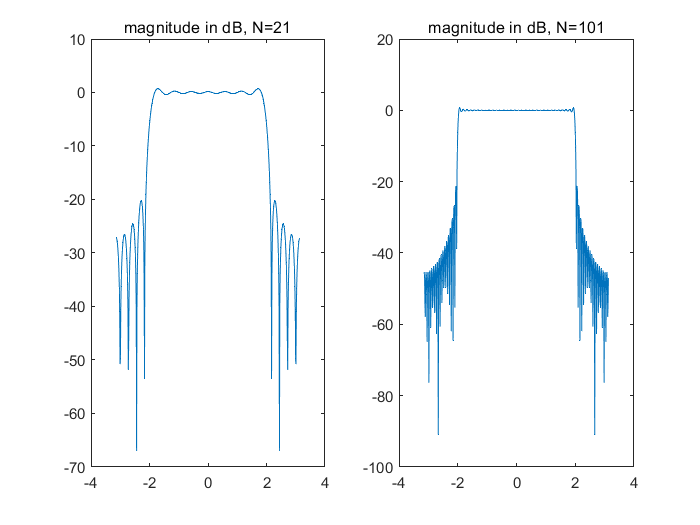

load nspeech2.mat;
N1=21;
N2=101;
h1 = LPFtrunc(N1);
[X1,w1] = DTFT(h1,512);
h2 = LPFtrunc(N2);
[X2,w2] = DTFT(h2,512);
% figure(1);
% subplot(121),plot(w1,abs(X1));title("magnitude not in dB, N=21");
% subplot(122),plot(w2,abs(X2));title("magnitude not in dB, N=101");
figure(2);
subplot(121),plot(w1,20*log10(abs(X1)));title("magnitude in dB, N=21");
subplot(122),plot(w2,20*log10(abs(X2)));title("magnitude in dB, N=101");